## Logistical Regression

Similar to linear discrimination, it estimates the highest probability of being part of a k class given a certain **x**.

Expression to iterate: beta(k+1) = betak + [ X^T * W * X ]^(-1) * X^T * [ **y** - **p** ]

where:

- y = [ y1, y2, ..., yn ]^T : class classifier (0 or 1)

- X = [ xia1, xia2, ... xian ]^T

- xia = [1 xi]^T

- p = [ P(x1, beta), P(x2, beta), ..., P(xn, beta) ]^T : probabilities vector

- W = [ P(x1, beta)*(1-P(x1, beta)), ..., 0; 0, P(x2, beta)*(1-P(x2, beta)), ..., 0; ...; 0, ..., P(xn, beta)*(1-P(xn, beta)) ]

x_data = [2 3; 5 2; 2 5; 5 8; 7 8; 7 6];
y_data = [0; 0; 0; 1; 1; 1];
n = length(x_data);

% Solving for X
X = zeros(n,3);
for i = 1:n
    xia = [1 x_data(i,1:end)];
    X(i,1:end) = xia;
end
X

X =      1     2     3
     1     5     2
     1     2     5
     1     5     8
     1     7     8
     1     7     6


% Rearranging y
y = y_data

y =      0
     0
     0
     1
     1
     1


beta = {};
beta{1} = zeros(3, 1);

% Solving for p
p = zeros(n,1);
for i = 1:n
    pxiab = (exp(beta{1}.' * X(i,1:end).'))/(1 + exp(beta{1}.' * X(i,1:end).'));
    p(i) = pxiab;
end
p

p =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


% Solving for W
W = zeros(n);
for i = 1:n
    expr = (exp(beta{1}.' * X(i,1:end).'))/(1 + exp(beta{1}.' * X(i,1:end).'));
    W(i,i) = expr*(1 - expr);
end
W

W =     0.2500         0         0         0         0         0
         0    0.2500         0         0         0         0
         0         0    0.2500         0         0         0
         0         0         0    0.2500         0         0
         0         0         0         0    0.2500         0
         0         0         0         0         0    0.2500


% Iterating to calculate beta
for i = 1:10
    beta{i+1} = beta{i} + (X.' * W * X)^(-1) * X.' * (y - p);

    p = zeros(n,1);
    for j = 1:n
        pxiab = (exp(beta{i+1}.' * X(j,1:end).'))/(1 + exp(beta{i+1}.' * X(j,1:end).'));
        p(j) = pxiab;
    end

    W = zeros(n);
    for j = 1:n
        expr = (exp(beta{i+1}.' * X(j,1:end).'))/(1 + exp(beta{i+1}.' * X(j,1:end).'));
        W(j,j) = expr*(1 - expr);
    end
end
beta.'

ans = 11×1 cell array
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}


% Solving for discrimination function
syms x1 x2
fd = vpa([1 x1 x2] * beta{end}, 4)

$$fd = 3.432\,x_{1}+3.519\,x_{2}-34.78$$

% Solving for separation frotier
sf = vpa(solve(fd, x2), 4)

$$sf = 9.884-0.9754\,x_{1}$$

% Classifying data
p = [2 9];

vpa(subs(fd, [x1 x2], p), 4)        % (+) = Above - class 2, (-) = Below - class 1

$$ans = 3.754$$

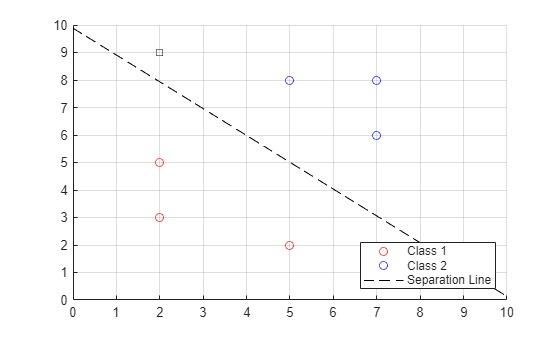

% Ploting data
figure;
hold on;
plot(x_data(1:3,1), x_data(1:3,2), 'ro');
plot(x_data(4:end,1), x_data(4:end,2), 'bo');
plot([0 10], [subs(sf,x1,0) subs(sf,x1,10)], 'k--');
plot(2, 9, 'ksquare');
xlim([0 10]); ylim([0 10]); xticks(0:10); yticks(0:10);
grid on; legend('Class 1', 'Class 2', 'Separation Line', 'Location','southeast');
hold off;

### Examples

Example 1

solve for:

- Apply logistical regression

- Determine what class does (4, 8) belongs to

x_data = [2 5; 4 3; 5 6; 5 8; 7 6; 6 4];
y_data = [0; 0; 0; 1; 1; 1];

beta = Logistical_regression(x_data, y_data, 7)

beta = 8×1 cell array
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}


% Solving for discrimination function
syms x1 x2
fd = vpa([1 x1 x2] * beta{end}, 4)

$$fd = 18.91\,x_{1}+4.613\,x_{2}-126.7$$

% Solving for separation frontier
sf = vpa(solve(fd, x2), 4)

$$sf = 27.45-4.1\,x_{1}$$

% Classifying data
p = [4 8];
vpa(subs(fd, [x1 x2], p), 4)           % (+) = Above - class 2, (-) = Below - class 1

$$ans = -14.09$$

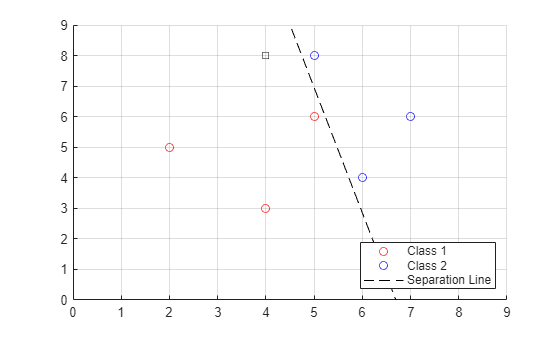

% Ploting data
figure;
hold on;
plot(x_data(1:3, 1), x_data(1:3, 2), 'ro');
plot(x_data(4:end, 1), x_data(4:end, 2), 'bo');
plot([0 9], [subs(sf,x1,0) subs(sf,x1,9)], 'k--');
plot(4, 8, 'ksquare');
xlim([0 9]); ylim([0 9]); xticks(0:9); yticks(0:9);
grid on; legend('Class 1', 'Class 2', 'Separation Line', 'Location','southeast');
hold off;